%RE_CS_701_A Fan Calculation
%Documento propiedad de Juan Gracia, Cooling Systems department, ISC
%FS Racing Team, para el poryecto de coche eléctrico.
%clc;clear;

%https://slideplayer.com/slide/4408178/

%OBJETO DEL DOCUMENTO:

%Proporcionar cálculo aproximado de los ventiladores necesarios en el
%accumulador, con tal de proporcionar la refrigeración necesaria. 

%Calor generado a disipar
%No se estudia la térmica de la celda. Si la temperatura superficial no es
%mayor a la crítica y se disipa el calor - OK. Medido en [W].
Qgen=1370;
Qgen=1500;
%Qgen=3186;
%Qgen=6;

%Temperatura de aire a la entrada
Tair_in=25;

%Dimensiones de celda, medido en [m]
Ncell=5*19*6;
Dcell=18e-3;
Hcell=65e-3;
Hcell_real=40e-3;
Scell=20.2e-3;

%Areas significativas y perímetro
A_free=6*Hcell_real*Scell;
A_max=(Scell-Dcell)*Hcell_real*(5+1);
P_max=5*(2*Hcell_real+2*(Scell-Dcell))+2*Hcell_real+(Scell-Dcell);

%Diámetro hhidráulico de la sección de velocidad máxima
Dh_max=4*A_max/P_max

Dh_max = 0.0042

%Propiedades del aire genéricas. Temperatura de evaluación 25-60ºC
%Capacidad calorífica del aire. Se supone constante con la teperatura.
%Medido en [J/KgK]
cp_air=1007;
%Número de Prandlt del aire.
Pr_air=0.706;
%Densidad del aire, medido en [kg/m3]
ro_air=1.127;
%Viscosidad del aire, medido en
nu_air=1.918e-5;
%Capacidad conductiva del aire, medido en [W/mK]
k_air=0.02662

k_air = 0.0266

%Densidad del auga, para presiones en columna de agua [kg/m3]
ro_wat=997;

%Superficie convectiva, medido en [m2]
Acon=(0.5*pi*Dcell^2+pi*Dcell*Hcell)*Ncell

Acon = 2.3852

%NOTA: No se está considerando que el aire no toca toda la celda. El area
%convectiva es menor. Extremos y parte del area lateral no está expuesta al
%caudal de aire libre.
Acon=(pi*Dcell*Hcell_real)*Ncell

Acon = 1.2893


%CÁLCULO DEL CAUDAL DE AIRE (Iteración manual):
%Caudal total de aire, medido en [CFM].
%q_air=47;
q_air=40.2;
%Convertido a [m3/s]
q_air=q_air*0.028/60

q_air = 0.0188

Uair_inf=(q_air/5)/A_free;
Uair_max=(q_air/5)/A_max;

%Número de Reynolds, evaluado en el punto de mayor velocidad / menor
%sección de paso. Denotado como max
Re_air_max=ro_air*Uair_max*Dh_max/nu_air

Re_air_max = 1.7490e+03

%Pérdida de carga según Reynolds, a iterar manualmente con la curva de
%caudal-presión del ventilador. Factor de correción 1
Xcorr=1;f=0.43;NL=19;

%Pérdida de carga, según link. Se entiende que expresados en [Pa] 
dP1=NL*Xcorr*f*(ro_air*Uair_max^2)/2;
%Prueba de cálculo de la caida de presión por otro método (termopedia)
EU=0.272+0.207e3/Re_air_max+0.102e3/Re_air_max^2-0.286/Re_air_max^3;
dP_row=EU*ro_air*Uair_max^2/2;
dP2=dP_row*NL;
%Como supuestamente el cálculo es similar, se emplea la media aritmética de
%ambos valores.
dP=(dP1+dP2)/2

dP = 221.7651

%Expresado en mmH2O para la curva del ventilador
dP=dP/(ro_wat/100)

dP = 22.2432

%Expresado en pulgadasH2O para la curva del ventilador
dP=dP*0.0393701

dP = 0.8757


%CÁLCULO COEFICIENTE DE CONVECCIÓN:
%No se entra en cálculo detallado del coeficiente de convección. De
%primeras, se supone la natural entorno a un cilindro. Escenario
%conservador. Medido en [W/m2K]. ¿FUENTE?
hcon=5;

%Expresión según Grimison, para Pr=0.7, 2000<Re<40000, y 10 o más filas de
%tubos/cilindros. Se supone que Pr_air es suficientemente similar a 0.7.
St=Scell;
Sl=Scell;

%Cálculo relación para selección de parámetros de Grimison
Pl=Sl/Dcell;
Pt=St/Dcell

Pt = 1.1222

%Se emplea el menor valor de 1.25, más cercano al del problema.
Grim_C1=0.348;
Grim_m=0.592;

%Aplicación de la expresión de Grimison
Nu_air=Grim_C1*Re_air_max^Grim_m

Nu_air = 28.9277


%Deducción del coeficiente de convección, con la longitud referenciada al
%diámetro de una de las celdas.
hcon=k_air*Nu_air/Dh_max

hcon = 183.8362

%TEMPERATURA SUPERFICIAL CELDAS:
%Se toma como diferencia de temperatura convectiva la temperatura
%superficial de las celdas y la temperatura media del aire.

%Temperaura de salida del aire se calcula por calor captado
Tair_out=Tair_in+Qgen/(ro_air*q_air*cp_air)

Tair_out = 95.4539

%Temperatura media del aire
Tair_mean=(Tair_out+Tair_in)/2

Tair_mean = 60.2269

%Delta de temperatura necesaria para el intercambio de calor requerido
dT=Qgen/(Acon*hcon)

dT = 6.3285

%Temperatura de superficie de celda
T_cell=Tair_mean+dT 

T_cell = 66.5555

%Temperatura de salida con el flujo de aire máximo posible por los
%ventiladores
Qgen/(ro_air*0.06*cp_air)

ans = 22.0286

Tair_out=Tair_in+Qgen/(ro_air*0.06*cp_air)

Tair_out = 47.0286

%Inercia térmica de la celda, si no se disipase calor ni al aire ni a la
%estructura del entorno. Medido en [J/KgK]
cp_cell=963.3;
%cp_cell=0.85
%Peso de una celda
m_cell=47e-3;

dT_cell=Qgen/(Ncell*m_cell*cp_cell)

dT_cell = 0.0581


close all;  
syms K E B T(t) C1
ode=Qgen-Acon*hcon*(T-Tair_in-Qgen*0.5/(q_air*cp_air*ro_air)+0.5*Ncell*cp_cell*m_cell*diff(T,t)/(q_air*cp_air*ro_air))==cp_cell*m_cell*Ncell*diff(T,t)

$$ode(t) = -\frac{675960082361955093112436247907\,\frac{\partial }{\partial t}T\left(t\right)}{5015409846326558592073728}-\frac{2286957968017751\,T\left(t\right)}{8796093022208}+\frac{9800591632683706309341542563699}{618970019642690137449562112}=\frac{7093721093067767\,\frac{\partial }{\partial t}T\left(t\right)}{274877906944}$$

%vpa(ode)
T(t)=dsolve(ode(t))

$$T(t) = \frac{C_{1}\,{\mathrm{e}}^{-\frac{333821852427534969824599586271\,t}{206180299850753084141963073147616}}}{160930360196511408004649713664}+\frac{9800591632683706309341542563699}{160930360196511408004649713664}$$

%Se resuleve cada uno de los términos
%T(t)=B/E-C1*exp(-E*t/K)
% T(t)=subs(T(t),B,Qgen+Acon*hcon*(Tair_in+0.5*Qgen/(q_air*ro_air*cp_air)));
% T(t)=subs(T(t),E,Acon*hcon);
% T(t)=subs(T(t),K,cp_cell*m_cell*Ncell);
% C1_val=solve(T(0)==Tair_in,C1);
% T(t)=vpa(subs(T(t),C1,C1_val))

%Track distance
td=963.8;

C1_val=solve(T(0)==Tair_in,C1);
T(t)=subs(T(t),C1,C1_val)

$$T(t) = \frac{9800591632683706309341542563699}{160930360196511408004649713664}-\frac{5777332627770921109225299722099\,{\mathrm{e}}^{-\frac{333821852427534969824599586271\,t}{206180299850753084141963073147616}}}{160930360196511408004649713664}$$

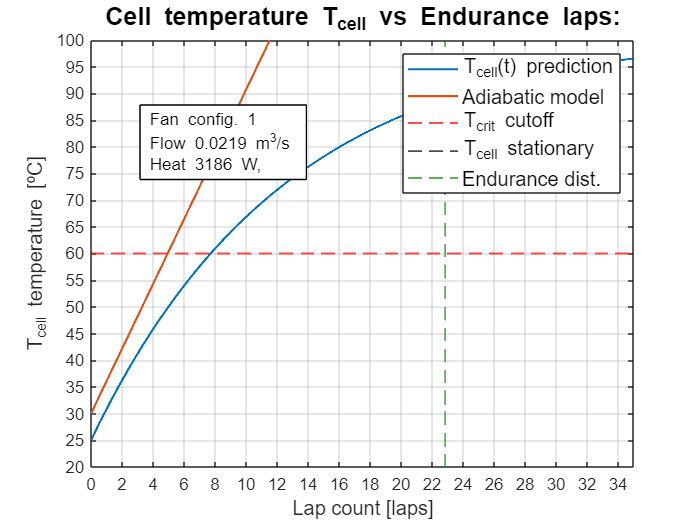

plot([0:1:3600]/49.19,T(0:1:3600),"LineWidth",1.3)
hold on
plot([0:1:3600]/49.19,dT_cell*[0:1:3600 ]+30,"LineWidth",1.3)

title('Cell temperature T_{cell} vs Endurance laps:','FontSize',15);
grid on; 
axis([0 35 20 100])
yticks([20:5:100]);xticks([0:2:35])
xlabel('Lap count [laps]','FontSize',12);
ylabel('T_{cell} temperature [ºC]','FontSize',12)
yline(60,"r--","LineWidth",1.1)
yline(T_cell,"k--","LineWidth",1.1)
xline(22000/td,"--","Color",[0.1 0.55 0.1],"LineWidth",1.1)
%xline([0:250:3900],"k--","LineWidth",1.1)
legend("T_{cell}(t) prediction","Adiabatic model","T_{crit} cutoff","T_{cell} stationary","Endurance dist.",'FontSize',12)
dim=[0.2 0.5 0.3 0.3];
str={['Fan config. 1'],['Flow ' num2str(q_air,3) ' m^3/s'],['Heat ' num2str(Qgen) ' W,']};
annotation('textbox',dim,'String',str,'FitBoxToText','on','BackgroundColor','w');
hold off

%Tf11(t)=T(t);
%Tf12(t)=T(t);
%Tf21(t)=T(t);
%Tf22(t)=T(t);

plot([0:1:3600]/49.19,Tf11(0:1:3600),"Color",[0 0.4470 0.7410],"LineWidth",1.3)
hold on
plot([0:1:3600]/49.19,Tf12(0:1:3600),"Color",[0 0.4470 0.7410],"LineWidth",1.3)
plot([0:1:3600]/49.19,Tf21(0:1:3600),"Color",[0.9290 0.6940 0.1250],"LineWidth",1.3)

Unrecognized function or variable 'Tf21'.

plot([0:1:3600]/49.19,Tf22(0:1:3600),"Color",[0.9290 0.6940 0.1250],"LineWidth",1.3)

yline(67.95,"--","Color",[0 0.4470 0.7410],"LineWidth",1.1)
yline(65.89,"--","Color",[0.9290 0.6940 0.1250],"LineWidth",1.1)

plot([0:1:3600]/49.19,dT_cell*[0:1:3600 ]+30,"Color",[0.8500 0.3250 0.0980],"LineWidth",1.3)
xline(22000/td,"--","Color",[0.1 0.55 0.1],"LineWidth",1.1)
yline(60,"r--","LineWidth",1.1)

grid on;
axis([0 35 20 100]);
yticks([20:5:100]);xticks([0:2:35])

ylabel('Cell temperature T_{cell} [ºC]','FontSize',12);
xlabel('Lap count [lap]','FontSize',12);
title('Cell temperature vs Endurance lap:','FontSize',15);
legend('Fan 1 config.','','Fan 2 config.','','','','Adiabatic model','Endurance dist.','Cut off temp.','FontSize',12)

hold off;













%Obetención del dato de calor medio generado
%Se computa a partir de los datos de potencia motor, obtenidos a partir de
%simulaciones de OptimumLap.
clc;clear;
 
%Archivo de referencia: OLPerfoance simulations_F.xlsx
EnAus12=readtable("OLPerfoance simulations_F.xlsx","Range","B65:J9705");
EnAus12_t=EnAus12{:,1};EnAus12_p=EnAus12{:,9}*1e3;
clear EnAus12;


EnGer10=readtable("OLPerfoance simulations_F.xlsx","Range","B9771:J17746");
EnGer10_t=EnGer10{:,1};EnGer10_p=EnGer10{:,9}*1e3;
clear EnGer10;

EnGer12=readtable("OLPerfoance simulations_F.xlsx","Range","B17812:J23508");
EnGer12_t=EnGer12{:,1};EnGer12_p=EnGer12{:,9}*1e3;
clear EnGer12;

CrGer12=readtable("OLPerfoance simulations_F.xlsx","Range","B23574:J28646");
CrGer12_t=CrGer12{:,1};CrGer12_p=CrGer12{:,9}*1e3;
clear CrGer12;

Accel=readtable("OLPerfoance simulations_F.xlsx","Range","B28712:J29463");
Accel_t=Accel{:,1};Accel_p=Accel{:,9}*1e3;
clear Accel;

Skid=readtable("OLPerfoance simulations_F.xlsx","Range","B29541:J32035");
Skid_t=Skid{:,1};Skid_p=Skid{:,9}*1e3;
clear Skid;

%Se calcula la corriente de descarga a partir de la potencia de descarga.
%Se divide entre la tensión nominal de la batería. Se asume representativa
%de la tensión del accu a lo largo de las pruebas dinámicas.
Un=342;
EnAus12_i=EnAus12_p/Un;
EnGer12_i=EnGer12_p/Un;
EnGer10_i=EnGer10_p/Un;
CrGer12_i=CrGer12_p/Un;
Skid_i=Skid_p/Un;
Accel_i=Accel_p/Un;

%Cálculos de calores generados en cada paso iterativo
EnAus12_q=calgen(EnAus12_i);
EnGer10_q=calgen(EnGer10_i);
EnGer12_q=calgen(EnGer12_i);
CrGer12_q=calgen(CrGer12_i);
Skid_q=calgen(Skid_i);
Accel_q=calgen(Accel_i);

%Se computa el calor medio espacial a modo de curiosidad. Se designa como
%asq de avera spatial q
EnAus12_asq=mean(EnAus12_q)
EnGer10_asq=mean(EnGer10_q)
EnGer12_asq=mean(EnGer12_q)
CrGer12_asq=mean(CrGer12_q)
Skid_asq=mean(Skid_q)
Accel_asq=mean(Accel_q)

%Se computa el calor medio temporal, empleado para cálculos térmicos. Se
%designa como atm
EnAus12_atm=atm(EnAus12_q,EnAus12_t)
EnGer10_atm=atm(EnGer10_q,EnGer10_t)
EnGer12_atm=atm(EnGer12_q,EnGer12_t)
CrGer12_atm=atm(CrGer12_q,CrGer12_t)
Skid_atm=atm(Skid_q,Skid_t)
Accel_atm=atm(Accel_q,Accel_t)





calgen(123.472)

function gen=calgen(v)
    gen_celda=570*0.013*(v/6).^2;
    gen_niquel=300*7.37e-5*(v/6).^2;
    gen_puntos=8*1.42e-4*(v/(6*8)).^2;
    gen_cobre=10*6.97716e-4*v.^2;
    gen_otros=5*10*1.42e-4*v.^2;
    gen=gen_celda+gen_niquel+gen_puntos+gen_cobre+gen_otros;
end

function out=atm(v,t)
    out=0;
    for i=1:1:(size(v)-1)
        out=out+v(i)*(t(i+1)-t(i));
    end
    out=out/t(end);
end


